# Simualtion

clear; clc;

n_mems = 10; noise_strength = 0.7;
N = 400; nTrials = 1000; trialLen = 100;

%% Initializing the Network properties
noise_window = 100; % in seconds
baseFolder = fullfile(pwd, 'Data', "N" + num2str(N), "nMems" + num2str(n_mems), "noise" + num2str(round(noise_strength*100))+ "%");
net = IzhikevichNetwork(N, 'heterogeneity', true, 'g_ee', 0.5, 'g_ei', 2, 'g_ie', 2, 'ExtoExDegree', 20, 'InhtoExDegree', 5, 'ExtoInhDegree', 5, 'baseFolder', baseFolder);

net.STDP = true;
net.noise = false;
net.sampling_rate = 5000;
net.sampling = false;
net.sigma_ex = noise_strength*5;
net.sigma_inh = noise_strength*2;

for i = 1:n_mems
    stim = Stimulation(net, trialLen, 2, 30, 50, 5);
    net.stimulation = true;
    net.stims = [stim];
    net.run(100000);

    net.stimulation = false;
    net.STDP = false;
    net.noise = true;
    net.run(noise_window*1000);
    net.STDP = true;
    net.noise = false;
end
save(fullfile(net.RecordingDirectory, "simInitialWorkSpace.mat"))

clear; clc;
load('C:\Users\Arshia\Desktop\StableLearningInBiologicalSNN\Analysis\Part5(NoisyConsolidation)\Data\N400\nMems10\noise100%\Jul_10_2025_10_08_03\simInitialWorkSpace.mat')
% net = obj;n_mems = 20;N = 400; nTrials = 1000; trialLen = 100;noise_window = 100;

data = net.getData();
firings = data.firings;

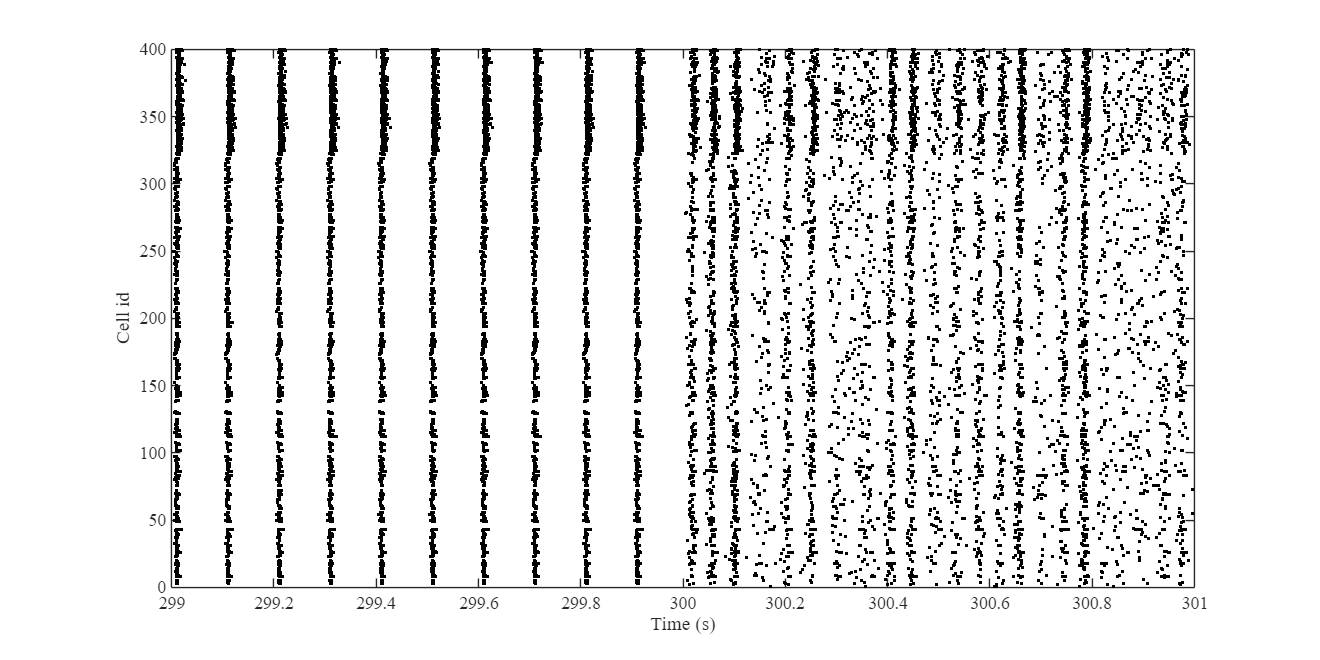

figure(Position=[0, 0, 1200, 600]);
index = (firings(1, :) < 301000) & (firings(1, :) > 299000);
plot(firings(1, index)/1000, firings(2, index), 'k.')
xlabel("Time (s)"); ylabel("Cell id")

# Spike density during the whole simulation process

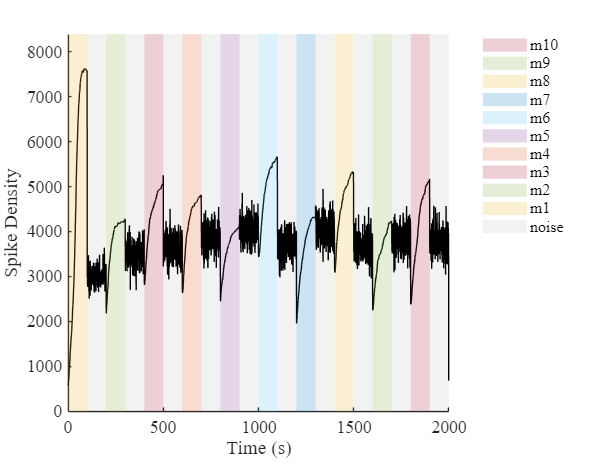

figure(); hold on; 
lerning_win = trialLen * nTrials / 1000;

counts = histcounts(firings(1, :), length(data.time));
plot(data.time, counts, 'k-', HandleVisibility='off'); 

HV = 'on';
for i = 1:n_mems
    area((i - 1)*(lerning_win + noise_window) + lerning_win + noise_window * [0, 0, 1, 1], 1.1*max(counts)*[0, 1, 1, 0], 'FaceColor', 'k' ,'FaceAlpha', 0.05, 'EdgeColor', 'none', DisplayName='noise', HandleVisibility=HV)
    area((i - 1)*(lerning_win + noise_window) + lerning_win * [0, 0, 1, 1], 1.1*max(counts)*[0, 1, 1, 0], 'FaceAlpha', 0.2, 'EdgeColor', 'none', DisplayName=sprintf("m%d", i))
    HV = 'off';
end

ylim([0, 1.1*max(counts)]);
ylabel("Spike Density"); xlabel("Time (s)");
legend(Location='bestoutside', Box='off');
hold off;

# Extracting the noisy windows and last trials in each learning trials

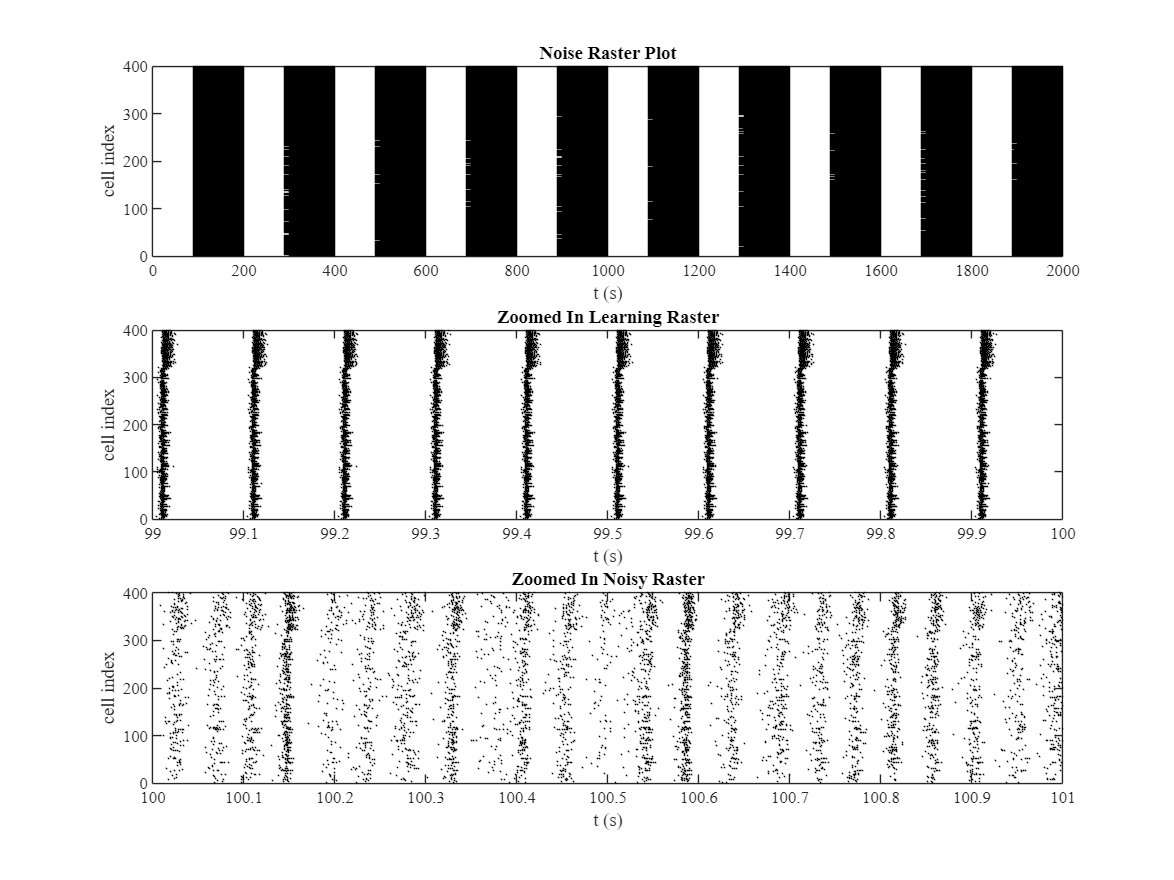

step = (lerning_win + noise_window)*1000;

f = containers.Map();
for i = 1:n_mems    
    index1 = (firings(1, :) > step*(i-1)+ 90000 ) & (firings(1, :) < step*(i-1)+100000);
    index2 = (firings(1, :) > step*(i-1)+100000 ) & (firings(1, :) < step*(i-1) + step);
    f(['mem', num2str(i)]) = firings(:, index1);
    f(['noise', num2str(i)]) = firings(:, index2);

end

ff = cell2mat(f.values());

figure(Position=[0 0 1200 900]);

subplot(3, 1, 1);
plot(ff(1, :)/1000, ff(2, :), 'k.', MarkerSize=1)
xlabel("t (s)")
ylabel("cell index")
title("Noise Raster Plot");

subplot(3, 1, 2);
idx = (ff(1, :) < 1000*lerning_win) & (ff(1, :) > 1000*lerning_win*0.99);
plot(ff(1, idx)/1000, ff(2, idx), 'k.', MarkerSize=1)
xlabel("t (s)")
ylabel("cell index")
title("Zoomed In Learning Raster");

subplot(3, 1, 3);
idx = (ff(1, :) < 1000*(0.01*noise_window + lerning_win)) & (ff(1, :) > 1000*lerning_win);
plot(ff(1, idx)/1000, ff(2, idx), 'k.', MarkerSize=1)
xlabel("t (s)")
ylabel("cell index")
title("Zoomed In Noisy Raster");

# Example of burst detection function on the rasters

ff_mem1 = f('mem1');
idx = (ff_mem1(1, :) < 1000*lerning_win) & (ff_mem1(1, :) > 1000*lerning_win*0.99);
ff_mem1 = ff_mem1(:, idx);
windSize = 3; timebinSize = 3; subset = 'ex'; thresh = 10;

[~, fig] = utils.BurstDetector(ff_mem1, thresh, true, subset, windSize, timebinSize);

Detected bursts (start, end) in ms:
   1.0e+04 *

    9.9004    9.9025
    9.9103    9.9124
    9.9202    9.9226
    9.9301    9.9325
    9.9403    9.9424
    9.9502    9.9526
    9.9601    9.9625
    9.9703    9.9724
    9.9802    9.9826
    9.9901    9.9925



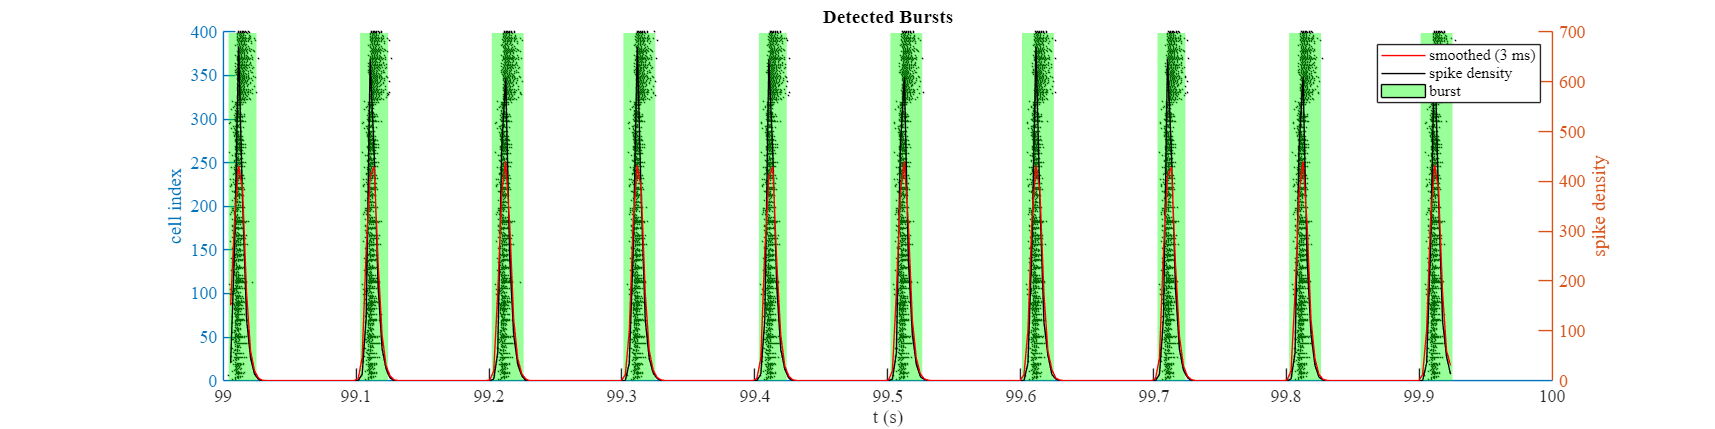

fig.Position = [0, 0, 1600, 400];


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ff_noise1 = f('noise1');
idx = (ff_noise1(1, :) < 1000*(0.02*noise_window + lerning_win)) & (ff_noise1(1, :) > 1000*lerning_win);
ff_noise1 = ff_noise1(:, idx);

[~, fig] = utils.BurstDetector(ff_noise1, thresh, true, subset, windSize, timebinSize);

Detected bursts (start, end) in ms:
   1.0e+05 *

    1.0001    1.0004
    1.0006    1.0008
    1.0010    1.0012
    1.0014    1.0016
    1.0019    1.0021
    1.0022    1.0025
    1.0027    1.0030
    1.0032    1.0034
    1.0037    1.0039
    1.0040    1.0042
    1.0044    1.0046
    1.0049    1.0050
    1.0053    1.0055
    1.0057    1.0060
    1.0063    1.0065
    1.0068    1.0070
    1.0072    1.0074
    1.0076    1.0078
    1.0081    1.0083
    1.0085    1.0087
    1.0089    1.0091
    1.0094    1.0096
    1.0098    1.0100
    1.0102    1.0104
    1.0106    1.0108
    1.0111    1.0114
    1.0117    1.0118
    1.0120    1.0123
    1.0125    1.0127
    1.0129    1.0131
    1.0133    1.0135
    1.0138    1.0140
    1.0141    1.0144
    1.0146    1.0148
    1.0150    1.0152
    1.0154    1.0156
    1.0159    1.0161
    1.0161    1.0162
    1.0164    1.0166
    1.0168    1.0171
    1.0172    1.0173
    1.0175    1.0175
    1.0175    1.0176
    1.0177    1.0181
    1.0183    1.0185
    1

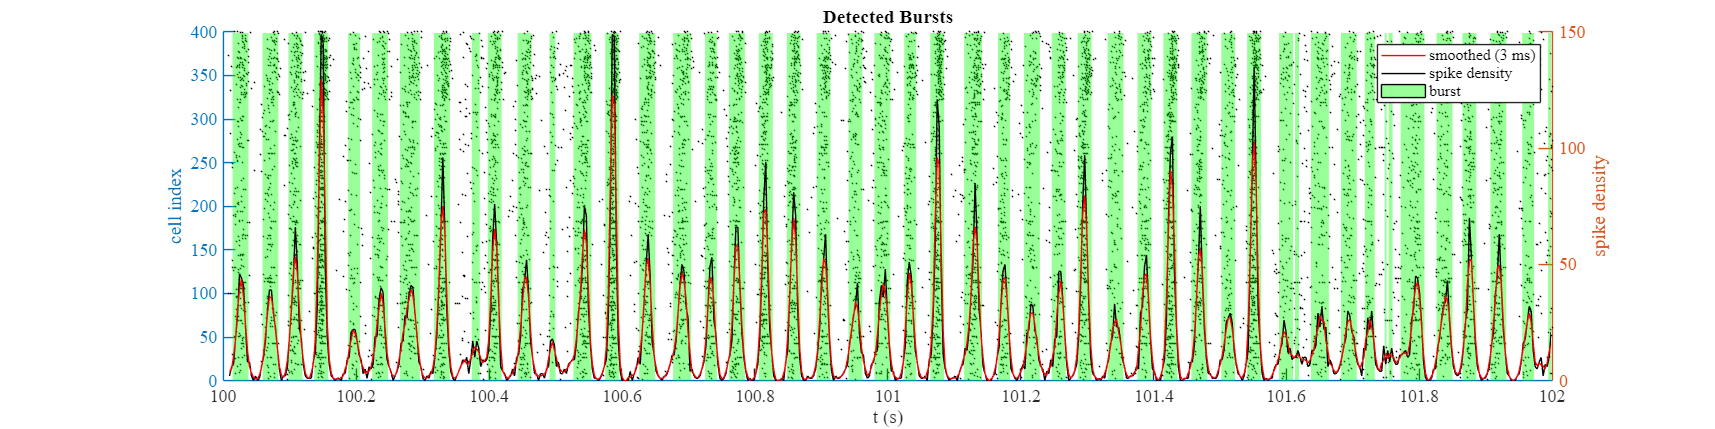

fig.Position = [0, 0, 1600, 400];

# Finding All bursts

%% ---------- build ordered key_list first ----------------------------
key_list = {};
for k = 1:n_mems
    mKey = sprintf('mem%d',  k);
    nKey = sprintf('noise%d',k);
    if isKey(f,mKey),   key_list{end+1} = mKey;  end
    if isKey(f,nKey),   key_list{end+1} = nKey;  end
end
% key_list = {'mem1','noise1','mem2','noise2', …}

%% ---------- extract values in that same order -----------------------
val_list = cellfun(@(k) f(k), key_list, 'UniformOutput', false);

%% ---------- make a NEW map in the desired order ---------------------
fOrdered = containers.Map( key_list , val_list );

% From here on, iterate over key_list and use fOrdered
bursts    = [];
num_burst = containers.Map();               % empty map

for k = 1:numel(key_list)
    
    key         = key_list{k};
    data        = fOrdered(key);            % value in correct sequence
    [bt, fig]   = utils.BurstDetector(data, thresh, false, subset, windSize, timebinSize);

    bursts      = [bursts; bt];
    num_burst(key) = size(bt,1);
end

Detected bursts (start, end) in ms:
   1.0e+04 *

    9.0004    9.0025
    9.0103    9.0124
    9.0202    9.0226
    9.0301    9.0325
    9.0403    9.0424
    9.0502    9.0526
    9.0601    9.0625
    9.0703    9.0724
    9.0802    9.0826
    9.0901    9.0925
    9.1003    9.1024
    9.1102    9.1126
    9.1201    9.1225
    9.1303    9.1324
    9.1402    9.1426
    9.1501    9.1525
    9.1603    9.1624
    9.1702    9.1726
    9.1801    9.1825
    9.1903    9.1924
    9.2002    9.2026
    9.2101    9.2125
    9.2203    9.2224
    9.2302    9.2326
    9.2401    9.2425
    9.2503    9.2524
    9.2602    9.2626
    9.2701    9.2725
    9.2803    9.2824
    9.2902    9.2926
    9.3001    9.3025
    9.3103    9.3124
    9.3202    9.3226
    9.3301    9.3325
    9.3403    9.3424
    9.3502    9.3526
    9.3601    9.3625
    9.3703    9.3724
    9.3802    9.3826
    9.3901    9.3925
    9.4003    9.4024
    9.4102    9.4126
    9.4201    9.4225
    9.4303    9.4324
    9.4402    9.4426
    9

# Computing the time delay vector of bursts

% f = f(:, f(2, :) <= 320);
[features, f_names] = utils.ExtractBurstFeatures(cell2mat(val_list), bursts, N);
features

features =     2.9000    5.4000    6.4000    5.0000    6.5000         0    4.9000    5.7000    5.8000    2.8000    5.8000    4.3000    5.2000    6.2000    5.8000    5.1000    6.0000    4.0000    5.0000    6.4000    5.3000    1.8000    3.9000    4.9000    5.9000    4.3000    6.1000    2.0000    6.1000    5.3000    4.8000    3.9000    7.0000    4.7000    5.3000    4.9000    2.0000    6.4000    5.2000    6.4000    5.1000    6.4000    6.4000    4.1000    4.8000    5.3000    2.9000    5.1000    6.4000    4.4000
    3.9000    6.4000    7.5000    6.0000    7.5000    1.0000    5.9000    6.8000    6.8000    3.8000    6.8000    5.4000    6.2000    7.2000    6.8000    6.1000    7.0000    5.0000    6.0000    7.4000    6.4000    2.8000    4.9000    5.9000    6.9000    5.3000    7.1000    3.0000    7.1000    6.3000    5.8000    4.9000    8.0000    5.7000    6.3000    5.9000    3.0000    7.4000    6.2000    7.4000    6.1000    7.4000    7.4000    5.1000    5.8000    6.3000    3.9000    6.1000    7.40

# Computing the distances between memory sequences and noisy bursts

%% ------------------------------------------------------------
%  CONFIGURATION  (tune as needed)

%% ------------------------------------------------------------
%  INPUTS
%  assemblies : [R × D] double  (rows = bursts / assemblies)
%  num_burst  : containers.Map with #bursts per memory
% -------------------------------------------------------------
assemblies = features(:, 1:net.Ne);                     % your variable

%% 1.  Row-wise z-score  ---------------------------------------------
X_mean     = nanmean(assemblies,2);
X_std      = nanstd (assemblies,0,2);
assemblies = (assemblies - X_mean) ./ X_std;    % rows now mean-0, sd-1
% assemblies = (assemblies - X_mean);    % rows now mean-0, sd-1

%% ----------------------------------------------------------
% key_list   : {'mem1','noise1','mem2','noise2', …}
% num_burst  : containers.Map  (key → #rows in assemblies)
% ----------------------------------------------------------
N_bursts_ord = cellfun(@(k) num_burst(k), key_list);   % 1×(2N) counts
cum          = cumsum([0, N_bursts_ord]);              % prefix-sum edges

rowsMem   = [];          % indices for mem bursts  → A
rowsNoise = [];          % indices for noise bursts → B

for k = 1:2:numel(key_list)        % step through mem / noise pairs
    % ---- mem k ------------------------------------------------------
    a1 = cum(k)   + 1;             % first row of mem-k
    a2 = cum(k+1);                 % last  row of mem-k
    rowsMem   = [rowsMem , a1:a2];

    % ---- noise k ----------------------------------------------------
    b1 = cum(k+1) + 1;             % first row of noise-k
    b2 = cum(k+2);                 % last  row of noise-k
    rowsNoise = [rowsNoise , b1:b2];
end

%% -------------- slice the big matrix -------------------------------
A = assemblies(rowsNoise  , :);      % all memory bursts
B = assemblies(rowsMem, :);      % all noise  bursts
% clear assemblies                   % free RAM

distSim = utils.ComputePearsonSimilarity(A, B, 50); distSim = distSim';
distSim_mems = utils.ComputePearsonSimilarity(B, B, 50);

# Similarity of the memories with each other

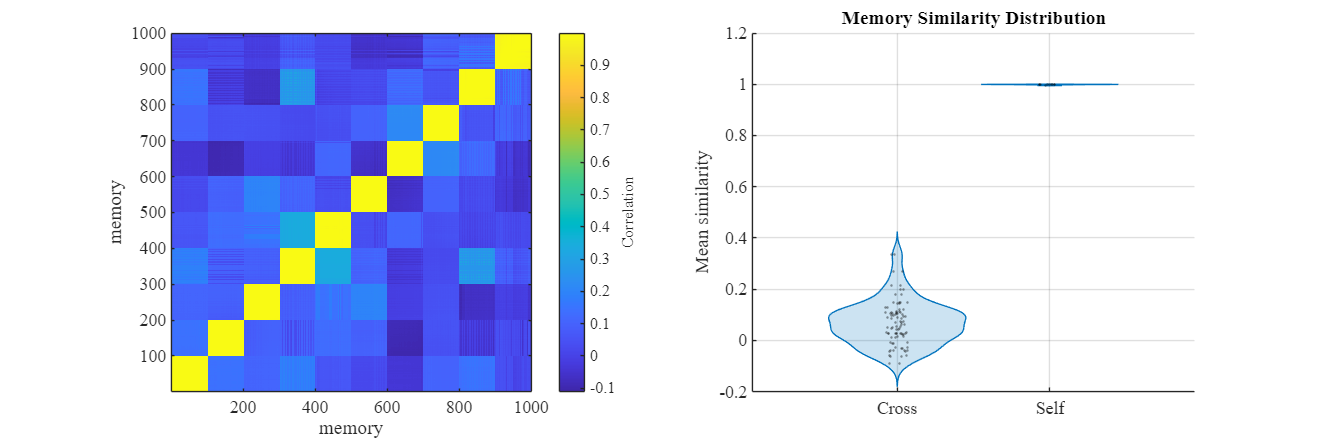

figure(Position=[0 0 1200 400]);
subplot(1, 2, 1);
distSimSlice = distSim_mems;

block   = 100;                         % 100×100 boxes
meanBox = squeeze( ...
            mean( ...
            mean( reshape(distSimSlice, block, n_mems, block, n_mems) , 1 , 'omitnan') ...
            , 3 , 'omitnan') );        % nM × nM

imagesc(distSimSlice);
cb = colorbar; xlabel("memory"); ylabel("memory"); cb.Label.String = "Correlation";
set(gca, 'ydir', 'normal')
% Diagonal: similarity of memories with themselves
selfSim = diag(meanBox);   % length-nM

% Off-diagonal: similarity of memories with other memories
mask = ~eye(n_mems);           % logical mask for off-diagonals
crossSim = meanBox(mask);  % (nM^2 - nM) elements

% Combine into table
data = [selfSim; crossSim];
group = categorical([repmat("Self", numel(selfSim),1);
         repmat("Cross", numel(crossSim),1)]);

subplot(1, 2, 2); hold on;
violinplot(group, data, 'DensityScale','width');

% Convert group to numeric x values
[~, ~, gIdx] = unique(group);  % gIdx is numeric: 1 for "Self", 2 for "Cross"

% Add jittered scatter
x_jitter = gIdx + 0.15 * (rand(size(gIdx)) - 0.5);  % small jitter around group
scatter(x_jitter, data, 3, 'k', 'filled', 'MarkerFaceAlpha', 0.4);

ylabel("Mean similarity");
title("Memory Similarity Distribution");
grid on;

# Imageshow of the similarity matrix betweem memory seqs and bursts

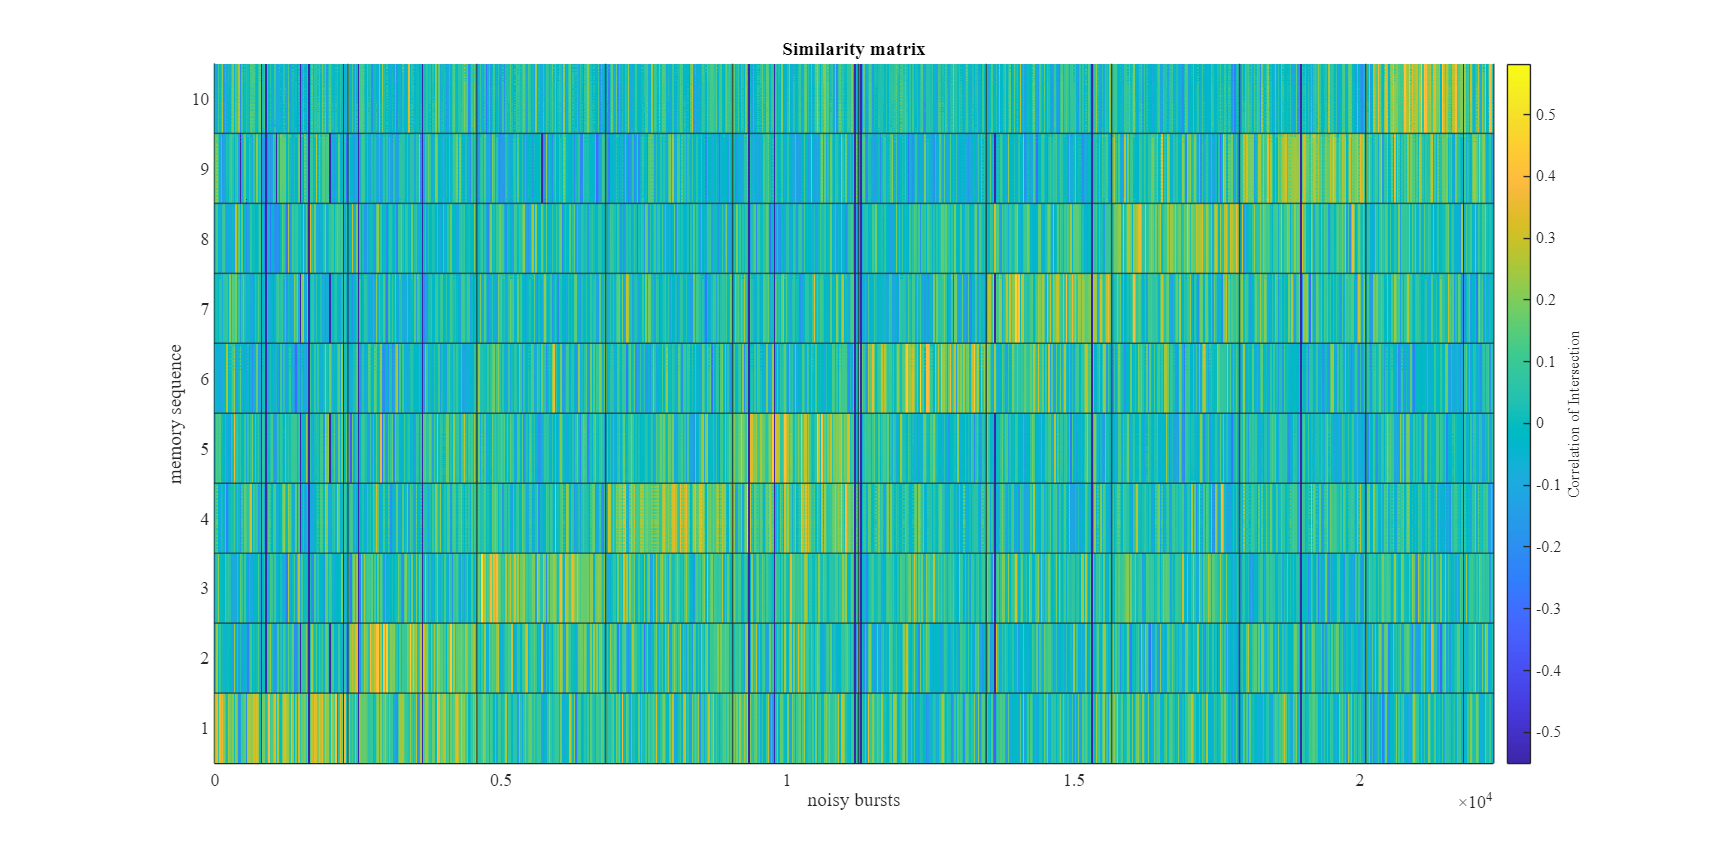

fig = figure(Position= [0, 0, 1600, 800]); hold on;
distSimSlice = distSim;
imagesc(distSimSlice);
colormap('parula');
cb = colorbar();
clim([min(distSimSlice, [], 'all'), max(distSimSlice, [], 'all')])
xlabel('noisy bursts'); ylabel('memory sequence'); cb.Label.String = "Correlation of Intersection";
yticks(100* (0.5:1:n_mems));
yticklabels(1:n_mems)
title("Similarity matrix");
ylim([0 n_mems]*100); xlim([0 sum(N_bursts_ord(2:2:end))]);
x_separation = cumsum(N_bursts_ord(2:2:end));
for i =1:n_mems
    xline(x_separation(i), 'LineStyle', '-', LineWidth=1)
    yline(i*100+0.5, 'LineStyle', '-', LineWidth=1)
end
set(gca, 'ydir', 'normal');

% saveas(fig, ['Plots' filesep 'image3.png'])

# Correlation of all bursts respect to one of the memories

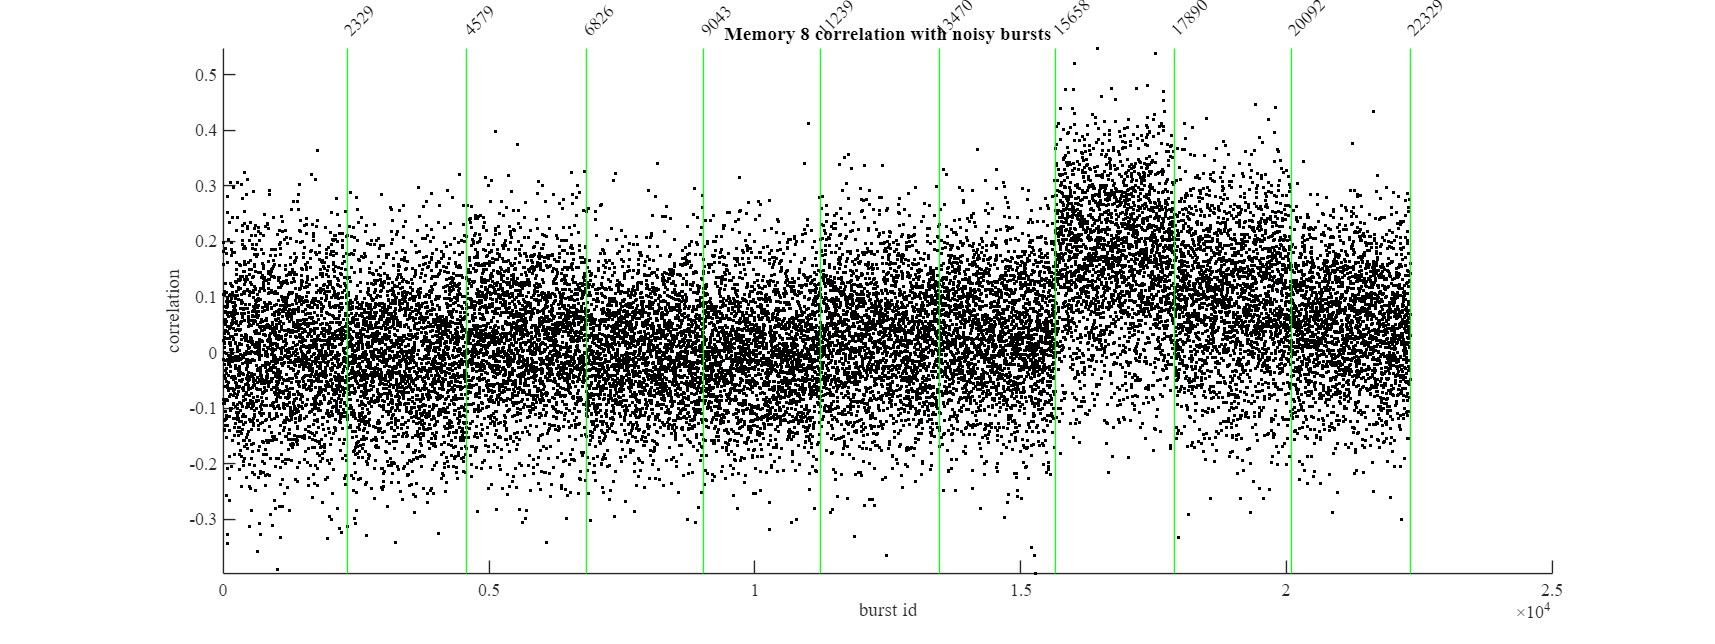

fig = figure(Position=[0 0 1600 600]); hold on;
mem = 8;
data = distSim((mem-1)*100 +1 :mem*100, 1:end); data = mean(data, 1); 

plot(data, 'k.')
counter= 0;
l = N_bursts_ord(2:2:end);
for b = l
    counter = counter + b;
    xline(counter*[1, 1], 'g-')
    text(counter, 1.05*max(data), num2str(counter), "Rotation",45)
    % boxplot(assemblies)
end
title(sprintf("Memory %d correlation with noisy bursts", mem))
ylim([min(data), max(data)])
xlabel("burst id")
ylabel("correlation")

% saveas(fig, ['Plots' filesep 'image4.png'])

# Preprocessing the data

data = zeros(n_mems, sum(N_bursts_ord(2:2:end)));
for mem = 1:n_mems
    temp = distSim((mem-1)*100 +1 :mem*100, :);
    data(mem, :) = mean(temp, 1);
end

noiseBurstLabels = repelem(1:n_mems,  N_bursts_ord(2:2:end));

index = [];
n = 0;
for num =  N_bursts_ord(2:2:end)
    index = [index; [n + 1, num + n]];
    n = num + n;
end

% Initialize data as a cell array
Data = cell(n_mems, n_mems);  
c_label = {};  % Category labels
g_label = {};  % Group labels

% Populate data and labels
for mem = 1:n_mems
    for i = 1:n_mems
        % Extract data for each (mem, i) combination
        temp = data(mem, index(i, 1):index(i, 2));
        temp = temp(:)';
        temp = temp(~isnan(temp));

        % Store data in the cell array
        Data{mem, i} = temp;  % Ensure each group data is a row vector

        % Define labels
        if mem == 1
            c_label{i} = ['noisy bursts ', num2str(i)];
        end
        g_label{mem} = ['mem', num2str(mem)];
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

data_stats = zeros(n_mems, n_mems, 4);
for mem = 1:n_mems
    for noise = 1:n_mems
        tempArr = Data{mem, noise};
        M = mean(tempArr);
        CI_upper = prctile(tempArr, 95);
        CI_lower = prctile(tempArr, 5);
        sigma = std(tempArr);
        
        data_stats(mem, noise, :) = [M, CI_lower, CI_upper, sigma];
    end
end

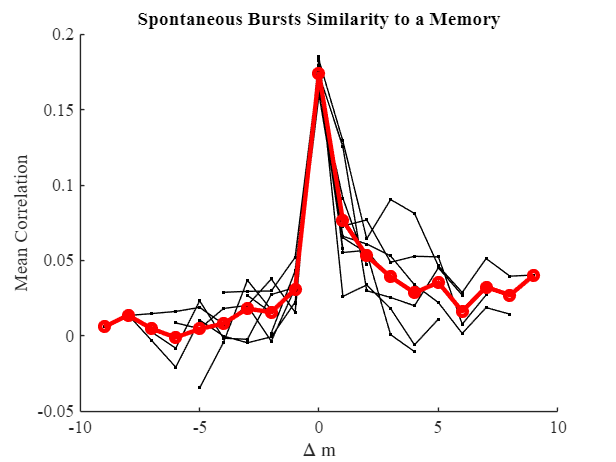

X = -n_mems+1:n_mems-1;
Y = nan(n_mems, length(X));
for mem=1:n_mems
    Y(mem, (n_mems:2*n_mems-1)-mem+1) = data_stats(mem, :, 1);
end

figure; hold on;
plot(X, Y, 'k.-')
plot(X, nanmean(Y, 1), 'ro-', LineWidth=3)
xlabel("$\Delta$ m", 'Interpreter', 'latex')
ylabel("Mean Correlation");
title("Spontaneous Bursts Similarity to a Memory");

% Call the function
% fig = figure(Position=[0 0 1600 400]);
% plotGroupedBox(Data, c_label, g_label);
% saveas(fig, ['Plots' filesep 'image5.png'])


function plotGroupedBox(data, category_labels, group_labels)
    % plotGroupedBox: Creates a grouped box plot with overlaid scatter points for each group.
    %
    % Parameters:
    %   data - Cell array: {category, group}, each cell is a numeric vector
    %   category_labels - Labels for main categories (x-axis ticks)
    %   group_labels - Labels for each sub-group (used in legend)

    % Check dimensions
    num_categories = length(category_labels);
    num_groups = length(group_labels);

    % Prep
    all_data = [];
    positions = [];
    categories = [];
    groups = [];
    scatter_x = [];
    scatter_y = [];

    offset = 0.15;  % group spacing
    base_pos = 1;
    position_counter = base_pos;

    colors = lines(num_groups);  % assign colors

    % Build data arrays
    for c = 1:num_categories
        for g = 1:num_groups
            group_data = data{c, g};
            if isempty(group_data), continue; end

            x_pos = position_counter + (g - (num_groups + 1) / 2) * offset;

            all_data = [all_data; group_data(:)];
            categories = [categories; repmat(c, length(group_data), 1)];
            groups = [groups; repmat(g, length(group_data), 1)];
            positions = [positions, x_pos];

            scatter_x = [scatter_x, x_pos + (rand(size(group_data)) - 0.5) * offset * 0.6];
            scatter_y = [scatter_y; group_data(:)];
        end
        position_counter = position_counter + 1;
    end

    % --- Plot ---
    hold on;
    box_h = boxplot(all_data, {categories, groups}, ...
        'positions', positions, ...
        'ColorGroup', groups, ...
        'Whisker', 1.5, ...
        'Symbol', '', ...
        'FactorSeparator', 1, ...
        'Widths', offset * 0.9);

    % Color boxes
    h = findobj(gca, 'Tag', 'Box');
    for j = 1:length(h)
        patch(get(h(j), 'XData'), get(h(j), 'YData'), colors(mod(j-1, num_groups)+1, :), ...
            'FaceAlpha', 0.3, 'EdgeColor', colors(mod(j-1, num_groups)+1, :), 'LineWidth', 1.2);
    end
    
    % violinplot(groups,all_data,GroupByColor=categories)

    % % Overlay scatter points
    % scatter(scatter_x, scatter_y, 1, 'k', 'filled', 'MarkerFaceAlpha', 0.3);

    % Axes and Labels
    xticks(base_pos:base_pos+num_categories-1);
    xticklabels(category_labels);
    xtickangle(30);
    ylabel('Correlation', 'FontSize', 14);
    xlabel('Noisy Bursts after Learning Memory $m$', 'Interpreter', 'latex', 'FontSize', 14);
    title('Similarity of Noisy Bursts with Different Memories', 'FontSize', 14);

    % Styling
    set(gca, 'FontSize', 12, 'Box', 'off', 'TickDir', 'out');
    xlim([0.5, position_counter - 0.5]);

    % Legend (dummy lines)
    for g = 1:num_groups
        plot(NaN, NaN, '-', 'LineWidth', 2, 'Color', colors(g, :));
    end
    legend(fliplr(group_labels), 'Location', 'bestoutside', 'Box', 'off');
    hold off;

    % Export if needed
    set(gcf, 'Units', 'inches', 'Position', [1, 1, 8, 4.5]);
end


% function plotGroupedViolin(data, category_labels, group_labels)
%     % plotGroupedViolin: Creates grouped violin plots with custom positions.
%     % Inputs:
%     %   data - Cell array: {category, group}, each cell is a numeric vector
%     %   category_labels - x-axis main category names
%     %   group_labels - labels for each sub-group (used in legend)
% 
%     % Setup
%     num_categories = length(category_labels);
%     num_groups = length(group_labels);
%     group_colors = lines(num_groups);
%     offset = 0.15;  % spacing between violins within category
% 
%     figure(); hold on;
%     violin_handles = gobjects(num_groups, 1);
% 
%     for c = 1:num_categories
%         base_x = c;  % main x position for the category
%         for g = 1:num_groups
%             this_data = data{c, g};
%             if isempty(this_data)
%                 continue;
%             end
%             % Calculate x position for this violin
%             x_pos = base_x + (g - (num_groups + 1)/2) * offset;
% 
%             % Plot violin at dummy position x = 1
%             h = violinplot(this_data, ones(size(this_data)), ...
%                            'FaceColor', group_colors(g, :), ...
%                            'DensityWidth', offset * 0.9);
% 
%             % Shift the violin from x = 1 to x = x_pos
%             for v = 1:length(h)
%                 if isprop(h(v), 'ViolinPlot')
%                     dx = x_pos - h(v).ViolinPlot.XData(1);  % offset shift
%                     h(v).ViolinPlot.XData = h(v).ViolinPlot.XData + dx;
%                     h(v).BoxPlot.XData = h(v).BoxPlot.XData + dx;
%                     h(v).ScatterPlot.XData = h(v).ScatterPlot.XData + dx;
%                 end
%             end
% 
%             % Store one handle per group for legend
%             if isempty(violin_handles(g))
%                 violin_handles(g) = h(1).ViolinPlot;
%             end
%         end
%     end
% 
%     % Axes formatting
%     xticks(1:num_categories);
%     xticklabels(category_labels);
%     xtickangle(30);
%     ylabel('Correlation', 'FontSize', 14);
%     xlabel('Noisy Bursts after Learning Memory $m$', 'Interpreter', 'latex', 'FontSize', 14);
%     title('Similarity of Noisy Bursts with Different Memories', 'FontSize', 14);
% 
%     % Legend
%     legend(violin_handles, group_labels, 'Location', 'bestoutside', 'Box', 'off');
% 
%     set(gca, 'FontSize', 12, 'Box', 'off', 'TickDir', 'out');
%     xlim([0.5, num_categories + 0.5]);
%     set(gcf, 'Units', 'inches', 'Position', [1, 1, 8, 4.5]);
% end



% [~, clusters, ~] = DimensionalityReductionPCA(features, 2, true, 4, f_names);
% figure; hold on;
% plot(clusters, 'ko')
% xlabel("burst id")
% ylabel("cluster id")
% counter = 0;
% 
% for key = num_burst.keys
%     s = key{1};
%     area([counter, counter + num_burst(s)], [4, 4], 'FaceAlpha', 0.3)
%     counter = counter + num_burst(s);
% end


% Select optimal number of clusters (K value) using specified range
fh = @(X,K)(kmeans(X,K,"Distance","cosine"));
eva = evalclusters(features,fh,"CalinskiHarabasz","KList",2:10);
clear fh
K = eva.OptimalK;
clusterIndices = eva.OptimalY;

% Display cluster evaluation criterion values
figure
bar(eva.InspectedK,eva.CriterionValues);
xticks(eva.InspectedK);
xlabel("Number of clusters");
ylabel("Criterion values - calinskiHarabaszCriterion");
legend("Optimal number of clusters is " + num2str(K))
title("Evaluation of Optimal Number of Clusters")
disp("Optimal number of clusters is " + num2str(K));
clear K eva

% Calculate centroids
transformedData = features./sqrt(sum(features.^2,2));
centroids = grpstats(transformedData,clusterIndices,"mean");
clear transformedData

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(features);
clusterMeans = grpstats(score,clusterIndices,"mean");
h2 = gscatter(score(:,1),score(:,2),clusterIndices);
for i2 = 1:numel(h2)
    h2(i2).DisplayName = strcat("Cluster",h2(i2).DisplayName);
end
clear h2 i2 score
hold on
h2 = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h2.DisplayName = "ClusterMeans";
clear h2 clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");